# Uniform 2-D SA-LSUN (State-Attentive  Locallay-Structured Unitary Network)

Please do not forget to run** setpath **in the top directory of this package, and then return to this directory.

Requirements: MATLAB R2022a

Contact address: Shogo MURAMATSU,

        Faculty of Engineering, Niigata University,

        8050 2-no-cho Ikarashi, Nishi-ku,

        Niigata, 950-2181, JAPAN

        [http://msiplab.eng.niigata-u.ac.jp/](http://msiplab.eng.niigata-u.ac.jp/)

 Copyright (c) 2022-2026, Shogo MURAMATSU, All rights reserved.

clc, clear

### Load Data

dstfolder = '../../../data/2dData';
files = dir(fullfile(dstfolder,'*.mat'));
data = load(fullfile(dstfolder,files(1).name));
u = data.u;

if canUseGPU
    disp("Use GPU")
    u = gpuArray(u);
end

Use GPU


[szy,szx,szt] = size(u);

visualizeSamples2d(gather(u), "Input data (SA-LSUN)");

nof = 1;
ky = 2*nof+1; % # of overlapping blocks (odd number)
kx = 2*nof+1;

     3     3



disp([ky kx])
blksz = [4 4]; % Block size
% # of coeffs
nCoefs = 2;

## SA-LSUN for 2-D Data

% Decimation factor (Strides)
stride = blksz; % [My Mx]

% Number of overlapping blocks (Polyphase order plus one)
ovlpFactor = [ky kx];

% Max epochs
maxEpochs = 100;

% No DC-leakage
noDcLeakage = true;

% SA-LSUN control-path (parameter estimator) settings
neighbor = [3 3];      % Number of neighbor blocks
nResBlocks = 3;        % Number of residual blocks
width = 2;             % Width (FC expansion factor)

### Definition of custom layers and networks 

Use a custom layer of Deep Learning Toolbox to implement Analysis LSUN.

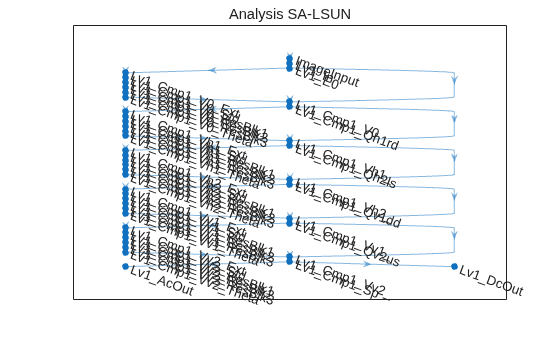

import tansacnet.salsun.*
analysislgraph = fcn_createsalsunlgraph2d([],...
    'InputSize',[szy szx],...
    'Stride',stride,...
    'OverlappingFactor',ovlpFactor,...
    'NumberOfVanishingMoments',noDcLeakage,...
    'NumberOfNeighborBlocks',neighbor,...
    'NumberOfResidualBlocks',nResBlocks,...
    'Width',width,...
    'Mode','Analyzer');
figure
plot(analysislgraph)
title('Analysis SA-LSUN')

#### Confirmation of the adjoint relation (perfect reconstruction)

wholelgraph = fcn_createsalsunlgraph2d([],...
    'InputSize',[szy szx],...
    'Stride',stride,...
    'OverlappingFactor',ovlpFactor,...
    'NumberOfVanishingMoments',noDcLeakage,...
    'NumberOfNeighborBlocks',neighbor,...
    'NumberOfResidualBlocks',nResBlocks,...
    'Width',width,...
    'Mode','Whole',...
    'ThetaMode','Reuse');
wholenet = dlnetwork(wholelgraph);

x = rand([szy szx],'single');
dlx = dlarray(x,'SSCB');
dly = wholenet.predict(dlx);
disp("MSE: " + num2str(mse(dlx,dly)))

MSE: 2.9223e-10


### Parameter optimization and approximation

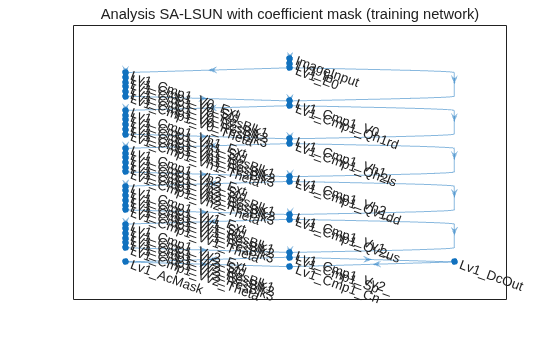

% Coefficient masking
nChsTotal = prod(stride);
coefMask = reshape([ones(nCoefs,1); zeros(nChsTotal-nCoefs,1)],2,[]).';
coefMask = coefMask(:);

iLv = 1;
strLv = sprintf('Lv%0d_',iLv);

import tansacnet.lsun.*
trainlgraph = analysislgraph.replaceLayer([strLv 'AcOut'],...
    maskLayer('Name',[strLv 'AcMask'],'Mask',coefMask(2:end),...
    'NumberOfChannels',nChsTotal-1));

iCmp = 1;
strCmp = sprintf('Cmp%0d_',iCmp);
trainlgraph = trainlgraph.addLayers(...
    lsunChannelConcatenation2dLayer('Name',[strLv strCmp 'Cn']));
trainlgraph = trainlgraph.connectLayers(...
    [strLv 'AcMask'],[strLv strCmp 'Cn/ac']);
trainlgraph = trainlgraph.connectLayers(...
    [strLv 'DcOut'],[strLv strCmp 'Cn/dc']);

figure
plot(trainlgraph)
title('Analysis SA-LSUN with coefficient mask (training network)')

## Training Process

### Training Setting

mbsize = 64;        % minibatch size
nofData = szt;
numIterationsPerEpoch = floor(nofData / mbsize);
numIterations = maxEpochs * numIterationsPerEpoch;

% Adam hyperparameters (cosine-decay learning rate, as in SA_LSUN.mlx)
B1 = 0.9;
B2 = 0.999;
ep = 1e-12;
initialLearnRate = 1e-3;
finalLearnRate = 1e-5;

avgGrad = [];
avgSqGrad = [];
iteration = 0;
epoch = 0;

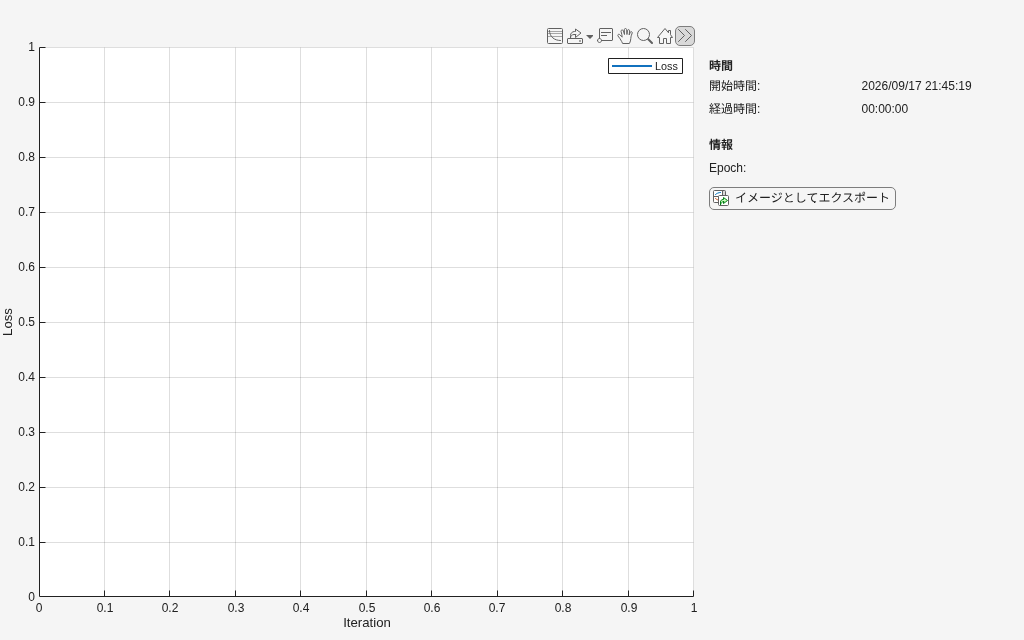

ds = arrayDatastore(gather(u),'IterationDimension',3);
mbq = minibatchqueue(ds,...
    'MiniBatchSize',mbsize,...
    'MiniBatchFcn',@preprocessMiniBatch,...
    'MiniBatchFormat',"SSCB",...
    "OutputEnvironment","auto",...
    'PartialMiniBatch','discard');

dlX0 = next(mbq);
trainnet = dlnetwork(trainlgraph,dlX0);
assert(trainnet.Initialized)
reset(mbq);

figure
monitor = trainingProgressMonitor(Metrics="Loss",Info="Epoch",XLabel="Iteration");

### Training

while epoch < maxEpochs && ~monitor.Stop
    epoch = epoch + 1;
    shuffle(mbq);

    while hasdata(mbq) && ~monitor.Stop
        iteration = iteration + 1;

        dlX = next(mbq);

        [gradients,loss] = dlfeval(@modelGradients,trainnet,dlX);

        learnRate = finalLearnRate + (initialLearnRate - finalLearnRate) ...
            * (1 + cos(pi * iteration/maxEpochs))/2;

        [trainnet,avgGrad,avgSqGrad] = adamupdate(trainnet,gradients,...
            avgGrad,avgSqGrad,iteration,learnRate,B1,B2,ep);

        recordMetrics(monitor,iteration,Loss=loss);
        updateInfo(monitor,Epoch=epoch + " of " + maxEpochs);
        monitor.Progress = 100 * iteration/numIterations;
    end
end

## Approximation by LSUN-base linear autoencoder 

wholelgraph = fcn_createsalsunlgraph2d([],...
    'InputSize',[szy szx],...
    'Stride',stride,...
    'OverlappingFactor',ovlpFactor,...
    'NumberOfVanishingMoments',noDcLeakage,...
    'NumberOfNeighborBlocks',neighbor,...
    'NumberOfResidualBlocks',nResBlocks,...
    'Width',width,...
    'Mode','Whole',...
    'ThetaMode','Reuse');

wholelgraph = wholelgraph.disconnectLayers([strLv 'AcOut'],[strLv 'AcIn']);
wholelgraph = wholelgraph.addLayers(...
    maskLayer('Name',[strLv 'AcMask'],'Mask',coefMask(2:end),...
    'NumberOfChannels',nChsTotal-1));
wholelgraph = wholelgraph.connectLayers([strLv 'AcOut'],[strLv 'AcMask']);
wholelgraph = wholelgraph.connectLayers([strLv 'AcMask'],[strLv 'AcIn']);

reconnet = dlnetwork(wholelgraph);
reconnet = copyLearnablesByName(reconnet,trainnet);

u_gathered = gather(u);
u_reconstruct = zeros(szy,szx,szt,'like',u_gathered);
for iSample = 1:szt
    dlXi = dlarray(reshape(u_gathered(:,:,iSample),szy,szx,1,1),'SSCB');
    u_reconstruct(:,:,iSample) = gather(extractdata(reconnet.predict(dlXi)));
end

## Result

mse_val = mean((u_gathered - u_reconstruct).^2,'all');
mae_val = mean(abs(u_gathered - u_reconstruct),'all');
disp("MSE: " + num2str(mse_val))
disp("MAE: " + num2str(mae_val))

figure
subplot(1,2,1)
imshow(u_gathered(:,:,1),[])
title("Original (sample 1)")
subplot(1,2,2)
imshow(u_reconstruct(:,:,1),[])
title("Approx. by SA-LSUN")

visualizeSamples2d(u_reconstruct, "Reconstructed by SA-LSUN (masked, nCoefs kept)");

## Definitions of local functions

Loss function

    
$$L(\mathbf{\theta}) = \|\mathbf{x}\|_2^2-\|F_\mathbf{\theta}(\mathbf{x})\|_2^2$$


where $F_\mathbf{\theta}(\cdot)$ is a unitary analyzer with a coefficient mask. $L(\mathbf{\theta})\geq 0$ is guaranteed.

function [gradients, loss] = modelGradients(dlnet, dlX)
% Forward data through the dlnetwork object.
dlY = forward(dlnet,dlX); % F(x)
% Compute loss.
Nx = size(dlX,4);
Ny = size(dlY,4);
loss = sum(dlX.^2,"all")/Nx-sum(dlY.^2,"all")/Ny;
% Compute gradients.
gradients = dlgradient(loss,dlnet.Learnables);
loss = double(gather(extractdata(loss)));
end

function netDst = copyLearnablesByName(netDst, netSrc)
tblDst = netDst.Learnables;
tblSrc = netSrc.Learnables;
for i = 1:height(tblSrc)
    idx = find(strcmp(tblDst.Layer,tblSrc.Layer{i}) & ...
        strcmp(tblDst.Parameter,tblSrc.Parameter{i}));
    if ~isempty(idx)
        tblDst.Value{idx} = tblSrc.Value{i};
    end
end
netDst.Learnables = tblDst;
end

function X = preprocessMiniBatch(dataCell)
X = cat(4,dataCell{:});
end

function visualizeSamples2d(u, figTitle, sampleIdx)
if nargin < 3
    sampleIdx = 1:min(4,size(u,3));
end
[szy,szx,szt] = size(u);
[X,Y] = meshgrid(1:szx,1:szy);
figure
nShow = numel(sampleIdx);
nCols = ceil(sqrt(nShow));
nRows = ceil(nShow/nCols);
for k = 1:nShow
    subplot(nRows,nCols,k)
    surf(X,Y,u(:,:,sampleIdx(k)),'EdgeColor','none')
    xlabel('x')
    ylabel('y')
    zlabel('u(x,y)')
    title("Sample " + sampleIdx(k) + "/" + szt)
end
sgtitle(figTitle)
end